% Define simulation parameters
T = 10;
dt = 0.01;
t = 0:dt:T;

% Define vehicle properties
m = 1;
I = 1e-1;
r = 0.1;
g = 9.81;

% Define waypoints
wpts = [0 5 10 15;
        0 10 5 10];
tpts = [0 T/3 2*T/3 T];

[p, v, a, ~] = minsnappolytraj(wpts, tpts, numel(t));

% Solve for rest of the states from spatial trajectory
x = p(1,:); y = p(2,:);
xdot = v(1,:); ydot = v(2,:);
xddot = a(1,:); yddot = a(2,:);

theta = atan2(-xddot, yddot + g);
thetadot = gradient(theta) / dt;
thetaddot = gradient(thetadot) / dt;

u1 = 1/2 * (m*(yddot + g) ./ cos(theta) + I * thetaddot / r);
u2 = 1/2 * (m*(yddot + g) ./ cos(theta) - I * thetaddot / r);

% Assembled reference trajectory
xref = [x; xdot; y; ydot; theta; thetadot];
uref = [u1; u2];

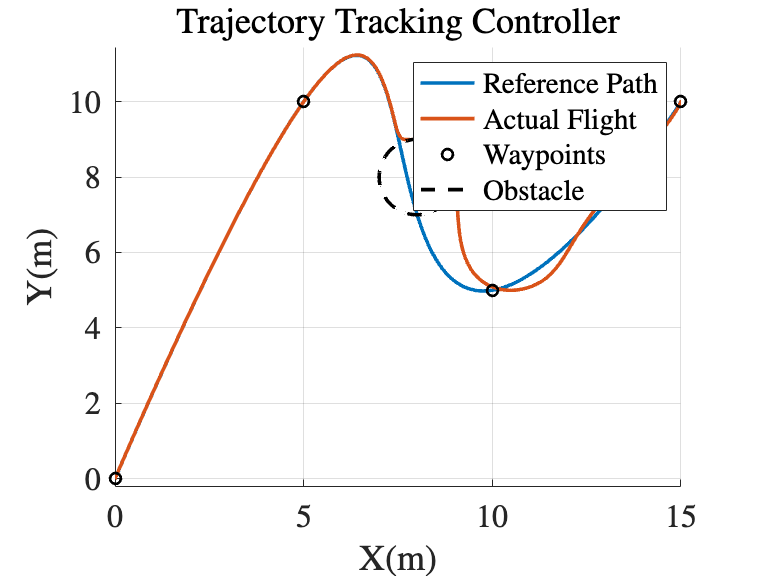

xnl = zeros(6, length(t));

u = zeros(2, length(t));
u(:,1) = m * g / 2 * [1; 1;];

obs = [8; 8];
robs = 1;

% Initialize the closest point tracker
last_idx = 1;

for i = 1:length(t) - 1

    xcur = xnl(:,i);
    
    % Find the Euclidean distance from current (x,y) to all (x,y) on the path.
    % Note: xref(1,:) is X, xref(3,:) is Y
    distances = vecnorm(xref([1, 3], :) - xcur([1, 3]));
    
    % Find the index of the closest point
    [~, closest_idx] = min(distances);
    
    % Safeguard: Prevent the reference point from moving backward
    closest_idx = max(closest_idx, last_idx);
    last_idx = closest_idx;
    
    % Extract the target state and nominal control based on space, not time
    xref_cur = xref(:, closest_idx);
    uref_cur = uref(:, closest_idx);
    % ----------------------------

    % Compute tracking error against the closest point
    xe = xcur - xref(:,i);

    [A, B] = getLinearization(xref_cur, uref_cur, m, I, r);

    % Compute Control Gain using LQR
    Q = diag([500 1 500 1 1 1]);
    R = diag([1 1]);

    sys = ss(A, B, eye(6), 0);
    k = lqr(sys, Q, R);

    % Feedback control
    ucur = uref_cur - k * xe;
 
    % Safety filter
    ucur = barrierFunction(xcur, ucur, obs, robs, m, g);

    u(:,i+1) = ucur;

    % Propagate the dynamics
    xdot = [xcur(2);
            -(ucur(1) + ucur(2)) * sin(xcur(5)) / m;
            xcur(4);
            (ucur(1) + ucur(2)) * cos(xcur(5)) / m - g;
            xcur(6);
            r*(ucur(1) - ucur(2)) / I];

    xnl(:,i+1) = xnl(:,i) + xdot * dt;

end


% --- Plotting ---
figure
hold on
plot(xref(1,:), xref(3,:))
plot(xnl(1,:), xnl(3,:))
plot(wpts(1,:), wpts(2,:), 'o', 'LineWidth', 1.5, 'Color', 'black')

% Plot Obstacle
th = 0:pi/50:2*pi;
plot(robs .* cos(th) + obs(1), robs .* sin(th) + obs(2), '--', 'Color','black');

title('Trajectory Tracking Controller')
legend('Reference Path', 'Actual Flight', 'Waypoints', 'Obstacle')
xlabel('X(m)')
ylabel('Y(m)')
axis equal

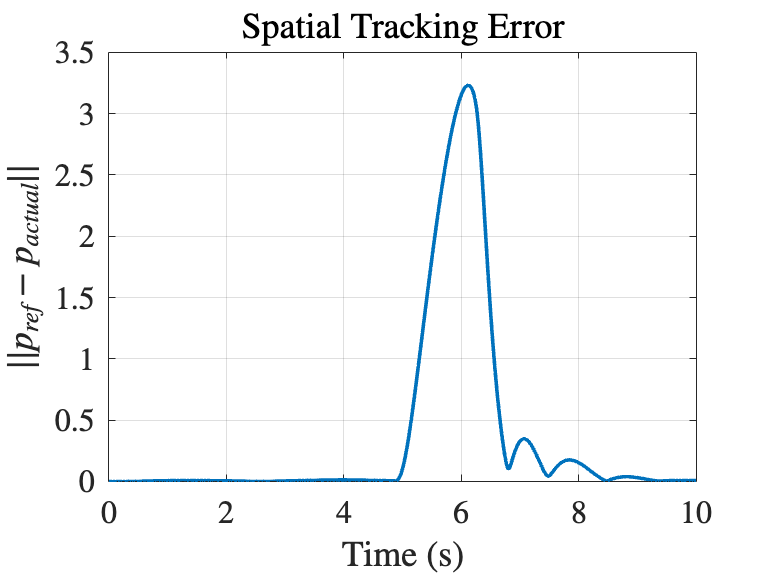


figure
plot(t, vecnorm(xnl([1, 3],:) - xref([1, 3],:)))
title('Spatial Tracking Error')
xlabel('Time (s)')
ylabel('$||p_{ref} - p_{actual}||$')

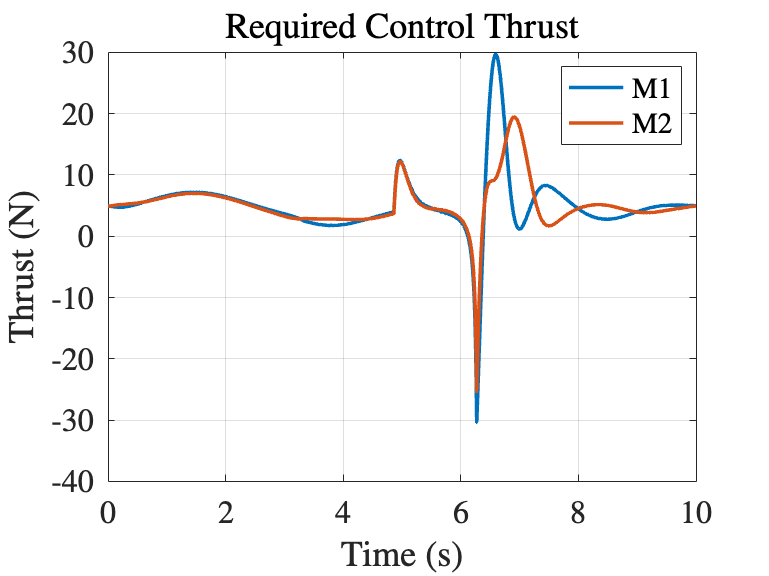


figure
plot(t, u)
title('Required Control Thrust')
xlabel('Time (s)')
ylabel('Thrust (N)')
legend('M1', 'M2')

function ustar = barrierFunction(x, unom, obs, Dobs, m, g)
    % Define safety parameters
    g1 = 10;
    g2 = 10;

    % Extract state information
    xpos = x(1); xdot = x(2);
    ypos = x(3); ydot = x(4);
    theta = x(5);

    p = [xpos; ypos];
    v = [xdot; ydot];

    xobs = obs(1);
    yobs = obs(2);

    d = p - obs;
    dn = norm(d);
    dx = xpos - xobs;
    dy = ypos - yobs;

    A = 1/dn * [ dx * sin(theta)/m - dy * cos(theta)/m ... 
                 dx * sin(theta)/m - dy * cos(theta)/m ];

    b = - (d'*v)^2 / dn^3 + (g1 * d' * v) / dn + (v'*v) / dn ...
        + (g2 * d' * v) / dn + (g1 * g2 * dn) - (g1 * g2 * Dobs) ...
        - (dy * g) / dn;

    if A * unom <= b
        ustar = unom;
    else
        ustar = unom - ((A * unom - b) / (A * A')) * A';
    end
end